# EchoServer Live Script 1 - Code Base

10 Mar 2022

Run EchoServer 3 and connect the Android clients first.

## Basic settings

% Ctrl + Enter to run each section

freq = [14240.625, 14700.   , 15159.375, 15618.75 , 16078.125, 16537.5  ,...
        16996.875, 17456.25 , 17915.625, 18375.   , 18834.375, 19293.75];
fs = 44100;

% high pass filter
fc = 10000;
[b,a] = butter(5, fc/(fs/2), 'high');

% device id
mi6 = 1;
motoz = 2;
pixel4 = 3;

## Send to device

#### Set to device 1: Mi 6

device = mi6;
disp("[I] Current device: 1 (Mi 6).")

[I] Current device: 1 (Mi 6).


writeline(server{device}, sig_str)

#### Set to device 2: Moto Z

device = motoz;
disp("[I] Current device: 2 (Moto Z).")

[I] Current device: 2 (Moto Z).


writeline(server{device}, sig_str)

#### Set to device 3: Pixel 4

device = pixel4;
disp("[I] Current device: 3 (Pixel 4).")

[I] Current device: 3 (Pixel 4).


writeline(server{device}, sig_str)

## Select a chirp to replace the default linear chirp (optional)

#### Chirp 0: mute

sig_str = sprintf('%f,', zeros(1,4000));
sig_str = sig_str(1:end-1);

#### Chirp 1: linear chirp

sig_len = 500;
chirp = zeros(1, sig_len);

f0 = 15000;
f1 = 20000;
w0 = f0 / fs * 2 * pi;
w1 = f1 / fs * 2 * pi;

for i = 1:sig_len
    K = sig_len * w0 / log(w1/w0);
    L = sig_len / log(w1/w0);
    phase = K * (exp(i/L) - 1.0);
    chirp(i) = sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

#### Chirp 2: step tones

sig_len = 41*12;
chirp = zeros(1, sig_len);
weights = [1.0 1.0 1.0 1.0 1.0 1.0
           1.0 1.0 1.0 1.0 1.0 1.0];
for i = 1:sig_len
    j = ceil(i/41);
    phase = 2 * pi * freq(j) * i / fs;
    chirp(i) = weights(j) * sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

#### Chirp 3: single tone

sig_len = 4000;
single_frequency = 19000;

for i = 1:sig_len
    phase = 2 * pi * single_frequency * i / fs;
    chirp(i) = sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

## Send chirp to selected device (optional)

writeline(server{device}, sig_str)

## Let the device play (or record, if it's set to mute)

writeline(server{device}, "Play.") % start
pause(5) % time for playback
writeline(server{device}, "Play.") % stop

% script for speaker calibration
writeline(server{mi6}, "Play.") % record
writeline(server{motoz}, "Play.")
pause(5)
writeline(server{motoz}, "Play.") % stop
writeline(server{mi6}, "Play.")

% script for speaker calibration
writeline(server{mi6}, "Play.") % record
writeline(server{pixel4}, "Play.")
pause(5)
writeline(server{pixel4}, "Play.") % stop
writeline(server{mi6}, "Play.")

#### Plot received data on calibrator

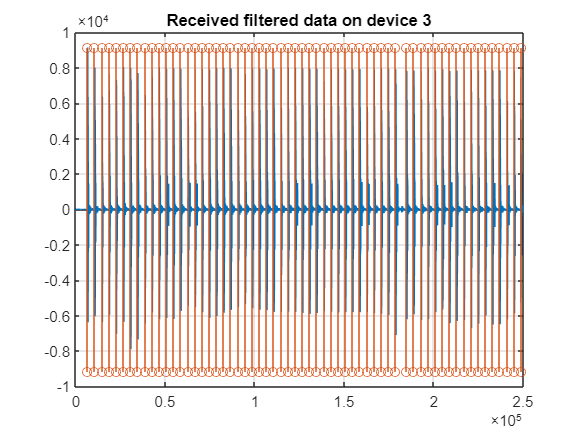

device = pixel4;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data on device " + num2str(device))
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

#### FFT of selected chunks (chirp part)

% please set which point to start
% the first several points are to be dropped

figure
N = 1024; % freq resolution = fs / N
r = 3 : start_l - 1; % kindly select the chunks
for i = r
    rr = start_list{device}(i);
    signal_duration = 500;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    Y = fft(signal_filtered, N);

    Fs = fs;                % Sampling frequency       
    L = signal_duration;    % Length of signal
    t = (0:L-1)*T;          % Time vector

    P2 = abs(Y/L);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = 0:(Fs/N):(Fs/2-Fs/N);
    hold on
    plot(f,P1(1:N/2))

    title('Single-Sided Amplitude Spectrum of X(t)')
    xlabel('f (Hz)')
    ylabel('|P1(f)|')
    hold on
end
stem(freq, max(P1)*ones(1, length(freq)))
hold off

#### STFT spectrogram of echoes

% plot fft of selected chunks (signal part)
% please set which point to start
% the first several points are to be dropped

device = pixel4;

r = 8 : start_l - 1; % kindly select the chunks
for i = 22
    % prepare data
    rr = start_list{device}(i) + 550; % 550:2920 (end not included)
    signal_duration = 2920 - 550 - 1;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f - 1,:); % end is included in MATLAB
    S = abs(ss) / max(max(abs(ss)));
    I = mat2gray(S);

    imagesc(tt * 170, ff / 1000, I); % distance as x-axis
    xlabel('distance / m'); ylabel('frequency / kHz');
    % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
    % xlabel('time / ms'); ylabel('frequency / kHz');

    title("Spectrogram (STFT) of Filtered Signal (550~2919)")
    set(gca, 'YDir', 'normal');
    colormap('hot')
end

hist(abs(ss(:)), 200)

#### STFT spectrogram of chirp (speaker of device 2: Moto Z)

device = mi6;

r = 4 : start_l - 1; % kindly select the chunks
ss_spec_mean = zeros(12, 9);
ss_amp_mean = zeros(length(freq), 1);
figure
for i = 4
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 500 - 1;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f - 1,:); % end is included in MATLAB
    S = abs(ss) / max(max(abs(ss)));
    I = mat2gray(S);

    figure
    imagesc(tt * 170, ff / 1000, I); % distance as x-axis
    xlabel('distance / m'); ylabel('frequency / kHz');
    % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
    % xlabel('time / ms'); ylabel('frequency / kHz');

    title("Spectrogram (STFT) of Filtered Signal (550~2919)")
    set(gca, 'YDir', 'normal');
    colormap('hot')

    
    ss_sum = sum(abs(ss), 2);
    plot(freq, ss_sum, '.')
    title("Averaged STFT of filtered chirp (Moto Z, 1~500)")
    xlabel("frequency / Hz"); ylabel("amplitude")
    hold on
    grid on

    ss_amp_mean = ss_amp_mean + ss_sum;
    ss_spec_mean = ss_spec_mean + abs(ss);
end
hold on
plot(freq, ss_amp_mean / length(r))

figure
S = abs(ss_spec_mean) / max(max(abs(ss_spec_mean)));
I = mat2gray(S);
imagesc(tt * 170, ff / 1000, I); % distance as x-axis
xlabel('distance / m'); ylabel('frequency / kHz');
% imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% xlabel('time / ms'); ylabel('frequency / kHz');

title("Averaged spectrogram of filtered chirp (Moto Z, 1~500)")
set(gca, 'YDir', 'normal');
colormap('hot')

frc_2 = ss_amp_mean / length(r);

#### STFT spectrogram of chirp (speaker of device 3: Pixel 4)

device = mi6;

r = 2 : start_l - 1; % kindly select the chunks
ss_spec_mean = zeros(12, 9);
ss_amp_mean = zeros(length(freq), 1);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 500 - 1;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f - 1,:); % end is included in MATLAB
    S = abs(ss) / max(max(abs(ss)));
    I = mat2gray(S);

%     figure
%     imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%     xlabel('distance / m'); ylabel('frequency / kHz');
%     % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%     % xlabel('time / ms'); ylabel('frequency / kHz');
% 
%     title("Spectrogram (STFT) of Filtered Signal (550~2919)")
%     set(gca, 'YDir', 'normal');
%     colormap('hot')

    
    ss_sum = sum(abs(ss), 2);
    plot(freq, ss_sum, '.')
    title("Averaged STFT of filtered chirp (Pixel 4, 1~500)")
    xlabel("frequency / Hz"); ylabel("amplitude")
    hold on
    grid on

    ss_amp_mean = ss_amp_mean + ss_sum;
    ss_spec_mean = ss_spec_mean + abs(ss);
end
hold on
plot(freq, ss_amp_mean / length(r))

figure
S = abs(ss_spec_mean) / max(max(abs(ss_spec_mean)));
I = mat2gray(S);
imagesc(tt * 170, ff / 1000, I); % distance as x-axis
xlabel('distance / m'); ylabel('frequency / kHz');
% imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% xlabel('time / ms'); ylabel('frequency / kHz');

title("Averaged spectrogram of filtered chirp (Pixel 4, 1~500)")
set(gca, 'YDir', 'normal');
colormap('hot')

frc_3 = ss_amp_mean / length(r);

% compare frc 2 and 3
figure
plot(freq, frc_2)
hold on
grid on
plot(freq, frc_3)
title("Comparison of FRCs")
xlabel("frequency / Hz"); ylabel("amplitude")
legend("Moto Z", "Pixel 4")